# Pràctica 2: Detecció de flors

## Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

### Carregar imatges i segmentar-les

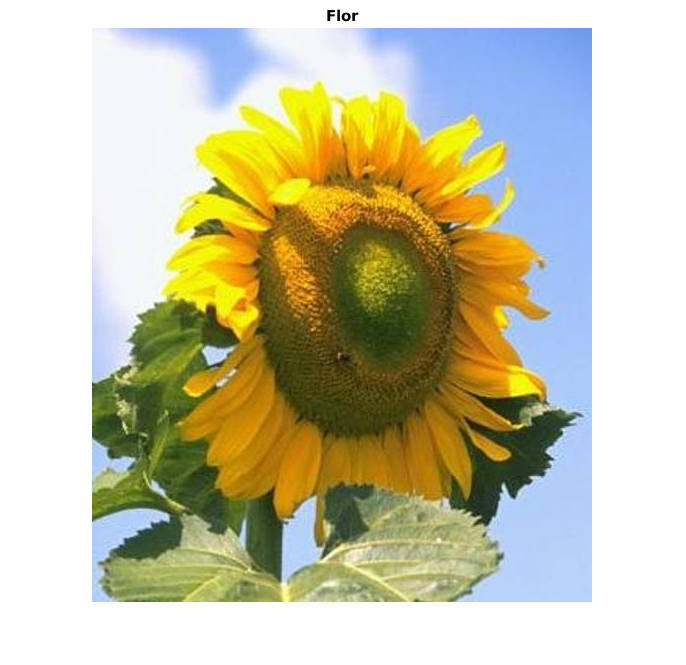

clear all;
close all;
im = imread('Segmentades/Girasol/image_0724.jpg');
figure, imshow(im), title('Flor')

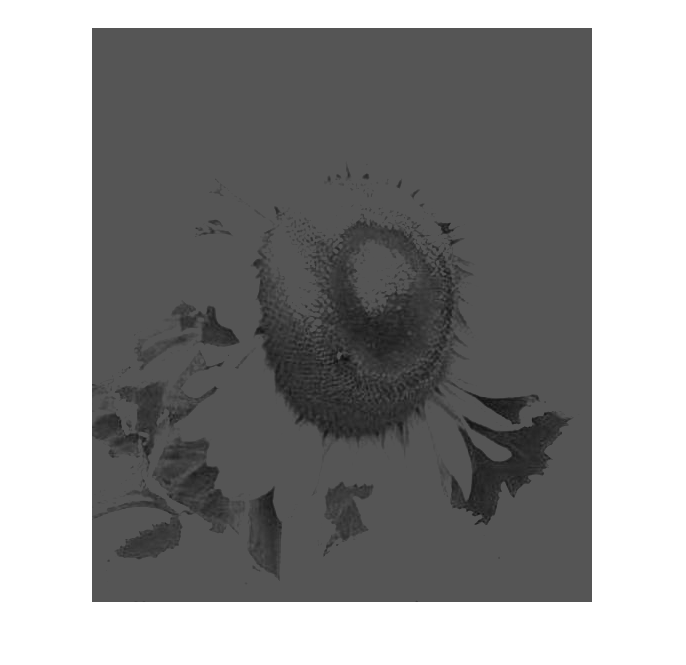

%FALTA FICAR LA IMATGE NORMALITZADA 
imgris = (im(:,:,1) + im(:,:,2) + im(:,:,3))./ 3;
imshow(imgris)

imnorm = double(mat2gray(imgris))

imnorm =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

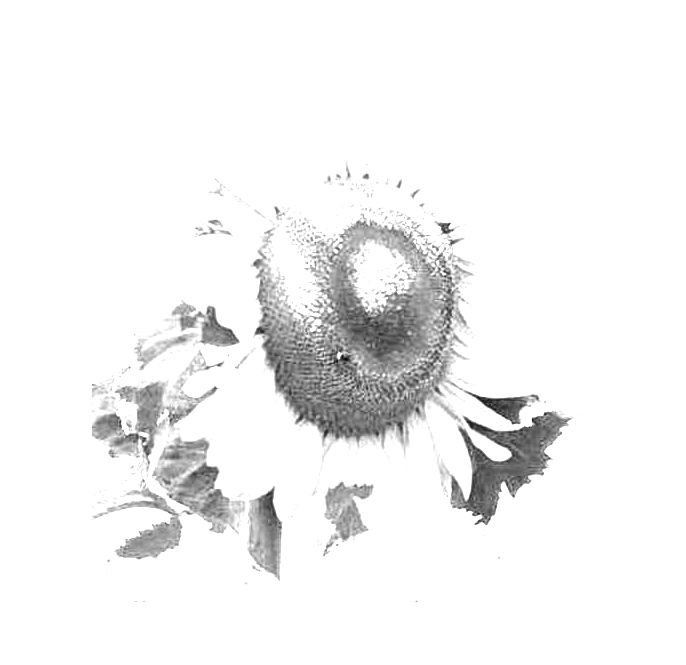

imshow(imnorm)

Proves


img = im2bw(im, graythresh(im));
img = ~img;

%EXTREURE FEATURES 
% https://www.mathworks.com/help/vision/ref/extractlbpfeatures.html
% https://www.mathworks.com/help/vision/ref/extracthogfeatures.html
% he vist que també podríem agafar la std2 i la mean2 de les imatges

% detectar corners i les més besties
corners   = detectFASTFeatures(rgb2gray(im));
strongest = selectStrongest(corners,3);
[hog2, validPoints,ptVis] = extractHOGFeatures(im,strongest)

hog2 = 3×36 single matrix
    0.1108    0.0386    0.0542    0.0232    0.1953    0.1979    0.0700    0.0665    0.0551    0.1997    0.1075    0.1631    0.0574    0.2728    0.2652    0.2728    0.2061    0.1165    0.0416    0.0345    0.0696    0.0677    0.2728    0.2728    0.0510    0.0307    0.0211    0.1551    0.1225    0.1980    0.0822    0.2728    0.2395    0.2654    0.2537    0.1410
    0.2525    0.1068    0.0107    0.0044    0.0398    0.0759    0.0878    0.1358    0.2490    0.3099    0.1503    0.0166    0.0127    0.0378    0.1316    0.1166    0.1350    0.2314    0.3099    0.3099    0.1103    0.0103    0.0417    0.1101    0.0949    0.1542    0.2649    0.3099    0.3099    0.0643    0.0350    0.0309    0.1524    0.1183    0.1147    0.1898
    0.1260    0.2122    0.2440    0.1160    0.1532    0.0965    0.0637    0.1293    0.1217    0.1975    0.2244    0.0818    0.0166    0.1078    0.2440    0.2440    0.1562    0.2049    0.1427    0.2440    0.2440    0.1745    0.2440    0.1284    0.0792  

validPoints =   3×1 cornerPoints array with properties:

    Location: [3×2 single]
      Metric: [3×1 single]
       Count: 3


ptVis = Visualization

   Type plot(ptVis) to visualize.

   Read-only properties:
                CellSize: [8 8]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


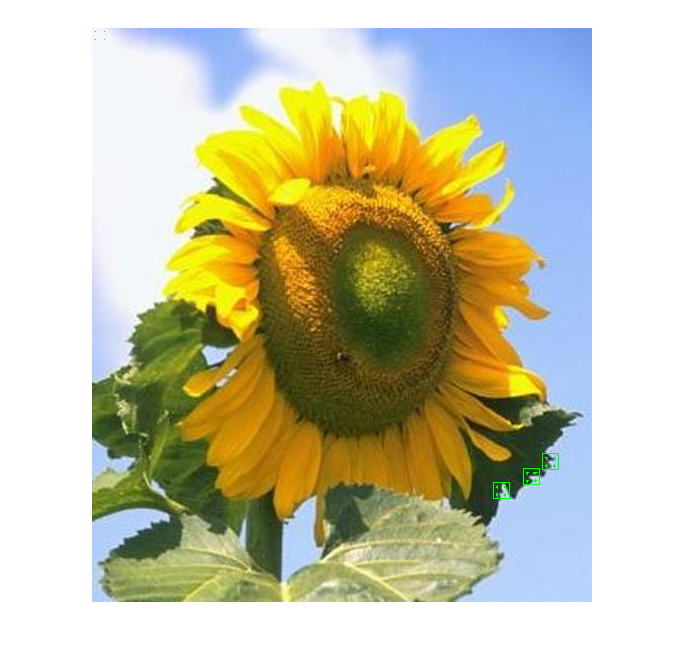

figure,imshow(im)
hold on
plot(ptVis,'Color','green');
hold off

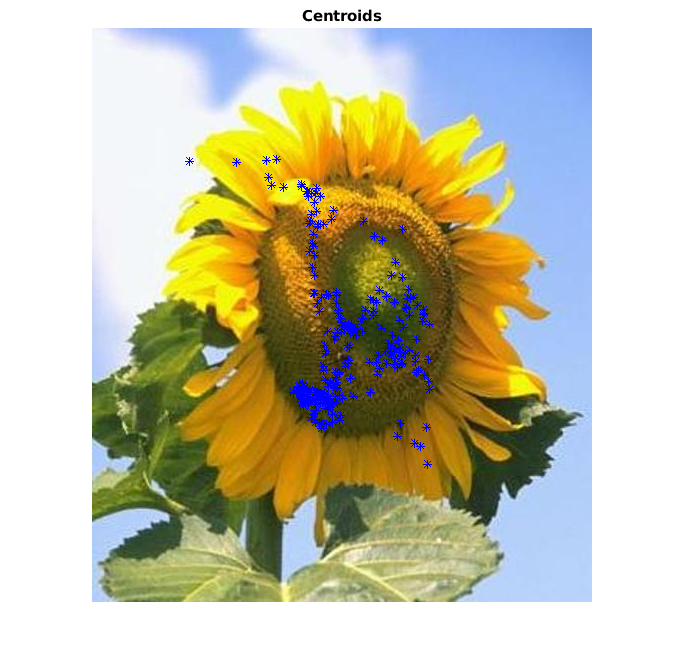



% information about local texture information
patternTextures = extractLBPFeatures(img);


[L, n] = bwlabel(img);
s = regionprops(im,'centroid');
%s = regionprops(L,'centroid','area','MajorAxisLength','MinorAxisLength','Orientation','BoundingBox');
figure, imshow(im), title('Centroids')
centroids = cat(1,s.Centroid);
hold on
plot(centroids(:,1),centroids(:,2),'b*')
hold off

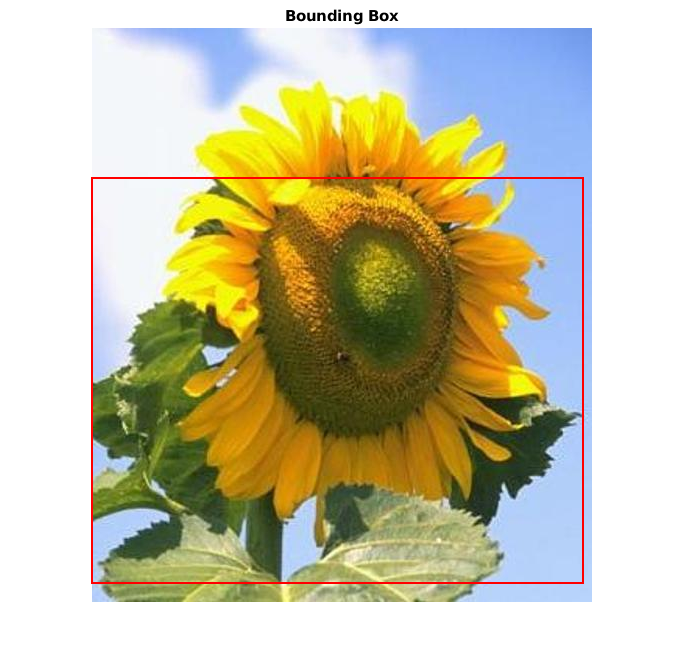



%NO FUNCIONA TT
st = regionprops(img, 'BoundingBox', 'Area' );
[maxArea, indexOfMax] = max([st.Area]);
imshow(im), title('Bounding Box')
hold on
rectangle('Position',[st(indexOfMax).BoundingBox(1),st(indexOfMax).BoundingBox(2),st(indexOfMax).BoundingBox(3),st(indexOfMax).BoundingBox(4)], 'EdgeColor','r','LineWidth',2 )
hold off

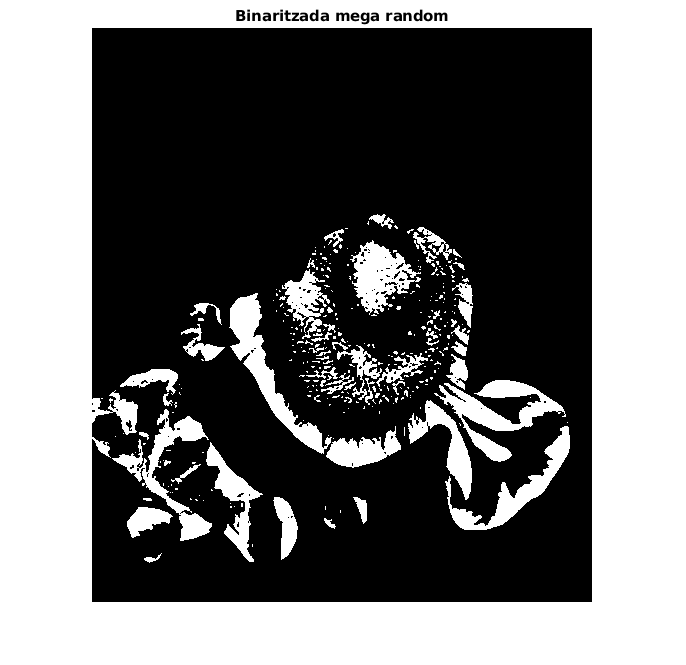


%BINARITZAR I LABLEJAR TO BE CONTINUED
binaritzada = imbinarize(imgris,'adaptive');
imshow(double(binaritzada)), title('Binaritzada mega random')

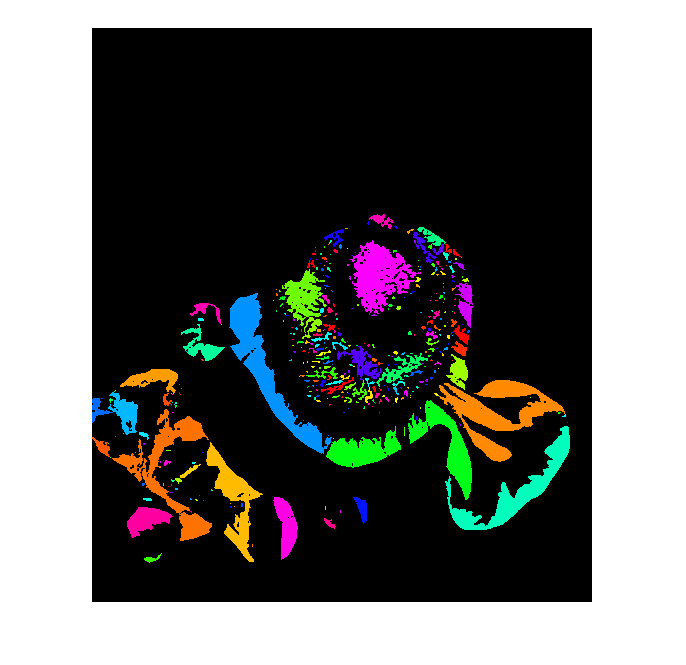

labeled = bwlabel(binaritzada,4);
coloredLabels = label2rgb(labeled, 'hsv','k','shuffle');
figure, imshow(coloredLabels);

### Detecció de vèrtexs (source: pràctica 11)

(Podria ser un feature la posició dels seus vèrtexs o la quantitat de vèrtexs)

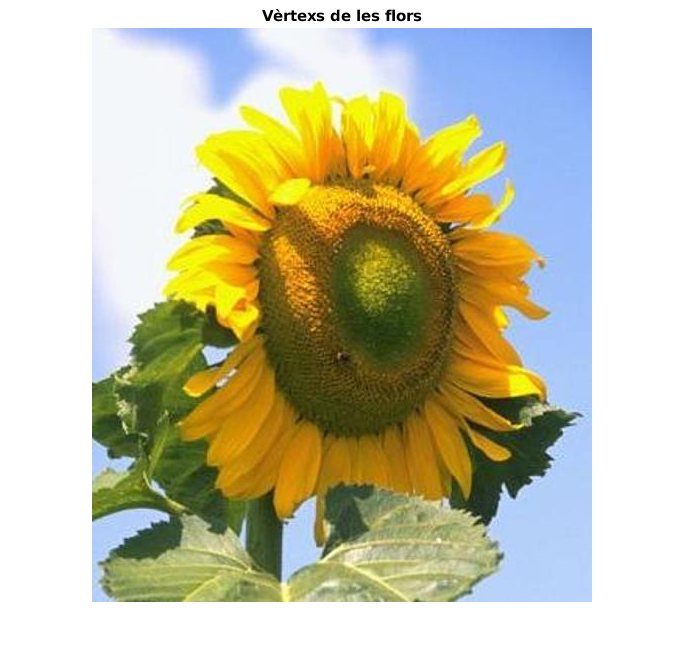

k = 0.04;
h = ones(5);
[rows cols] = size(h);
h = h./(rows * cols);

sobel = [-1 0 1;
         -2 0 2;
         -1 0 1];
iX = imfilter(im,sobel,'conv');
iY = imfilter(im,sobel,'conv');
R = (imfilter(iX.^2,h,'conv').*imfilter(iY.^2,h,'conv')) - imfilter(iX.*iY,h,'conv').^2-k.*(imfilter(iX.^2,h,'conv')+imfilter(iY.^2,h,'conv')).^2;


ee = strel('cube',3);
dilatada = imdilate(R,ee);
R(dilatada>R) = 0;
RL = (R > 0);
figure,imshow(im), title('Vèrtexs de les flors')
[ys xs] = find(RL);
hold on
plot(xs,ys,'s','color','red')
hold off

### Color (source:pràctica 10)

Podem partir d'aquí, no obstant a la pràctica només miràvem els RB i no RGB

Npatches = 300;

acum = 0

rb = NormalitzaRGB(im);
for j = 1:Npatches
    rb2 = patch_aleatori(rb,25,65);
    h = histo2D(rb2, 16);
    h = imgaussfilt3(h,1.5);
    P(j) = h
end

acum = 0.9826

acum = 2.0487

acum = 3.0487

acum = 4.0219

acum = 5.0218

acum = 6.0626

acum = 7.2220

acum = 8.2826

acum = 9.2568

acum = 10.2568

acum = 11.2568

acum = 12.4093

acum = 13.4091

acum = 14.4020

acum = 15.4650

acum = 16.6260

acum = 17.5665

acum = 18.6259

acum = 19.7216

acum = 20.7655

acum = 21.8450

acum = 22.8434

acum = 23.8446

acum = 25.0004

acum = 25.9255

acum = 26.9255

acum = 27.8820

acum = 28.9037

acum = 29.8947

acum = 30.9515

acum = 31.9512

acum = 33.1201

acum = 34.0631

acum = 35.1077

acum = 36.0345

acum = 37.0344

acum = 38.1404

acum = 39.0860

acum = 40.0860

acum = 41.1021

acum = 42.1020

acum = 43.0469

acum = 44.0469

acum = 45.0881

acum = 46.1162

acum = 47.2673

acum = 48.3810

acum = 49.4195

acum = 50.4501

acum = 51.4648

acum = 52.4872

acum = 53.4872

acum = 54.4955

acum = 55.4955

acum = 56.4955

acum = 57.4969

acum = 58.5206

acum = 59.5908

acum = 60.6626

acum = 61.7892

acum = 62.7892

acum = 63.7892

acum = 64.7473

acum = 65.7462

acum = 66.7072

acum = 67.7329

acum = 68.7337

acum = 69.8444

acum = 70.8497

acum = 71.8497

acum = 72.8081

acum = 73.8103

acum = 74.8381

acum = 76.0012

acum = 77.1496

acum = 78.1496

acum = 79.1496

acum = 80.1124

acum = 81.2847

acum = 82.2428

acum = 83.2428

acum = 84.2336

acum = 85.1740

acum = 86.1609

acum = 87.2234

acum = 88.3451

acum = 89.3042

acum = 90.2662

acum = 91.2662

acum = 92.2363

acum = 93.2919

acum = 94.2396

acum = 95.2395

acum = 96.2566

acum = 97.2899

acum = 98.3001

acum = 99.3001

acum = 100.2573

acum = 101.4419

acum = 102.5684

acum = 103.5528

acum = 104.6140

acum = 105.7592

acum = 106.7545

acum = 107.9192

acum = 108.9192

acum = 109.9885

acum = 111.1071

acum = 112.1597

acum = 113.1258

acum = 114.1339

acum = 115.2233

acum = 116.1740

acum = 117.1740

acum = 118.1465

acum = 119.1465

acum = 120.0769

acum = 121.1728

acum = 122.1728

acum = 123.2012

acum = 124.1242

acum = 125.1507

acum = 126.1550

acum = 127.1550

acum = 128.1550

acum = 129.1539

acum = 130.1592

acum = 131.1604

acum = 132.1881

acum = 133.2144

acum = 134.2139

acum = 135.2128

acum = 136.3603

acum = 137.3603

acum = 138.3164

acum = 139.3164

acum = 140.4567

acum = 141.5288

acum = 142.6394

acum = 143.6394

acum = 144.6546

acum = 145.6546

acum = 146.6126

acum = 147.6126

acum = 148.6126

acum = 149.5651

acum = 150.5577

acum = 151.5928

acum = 152.5133

acum = 153.5133

acum = 154.6157

acum = 155.6951

acum = 156.6951

acum = 157.8397

acum = 158.8354

acum = 159.8337

acum = 160.7769

acum = 161.7209

acum = 162.8128

acum = 163.8128

acum = 164.8125

acum = 165.9344

acum = 166.9326

acum = 167.9326

acum = 168.9326

acum = 170.0325

acum = 171.0372

acum = 172.0419

acum = 173.1243

acum = 174.0423

acum = 175.0640

acum = 176.0735

acum = 177.0697

acum = 178.0697

acum = 179.0697

acum = 180.2340

acum = 181.2383

acum = 182.2519

acum = 183.2737

acum = 184.4259

acum = 185.4162

acum = 186.4295

acum = 187.3795

acum = 188.5449

acum = 189.6238

acum = 190.6238

acum = 191.7990

acum = 192.7291

acum = 193.7290

acum = 194.7779

acum = 195.7445

acum = 196.8022

acum = 197.8166

acum = 198.8679

acum = 199.8087

acum = 200.8408

acum = 201.8088

acum = 202.8060

acum = 203.7258

acum = 204.8015

acum = 205.8025

acum = 206.7791

acum = 207.8177

acum = 208.9759

acum = 209.9759

acum = 211.0283

acum = 211.9794

acum = 213.0711

acum = 214.0658

acum = 215.1021

acum = 216.2702

acum = 217.3465

acum = 218.3215

acum = 219.4040

acum = 220.4286

acum = 221.4561

acum = 222.4347

acum = 223.4032

acum = 224.4032

acum = 225.3913

acum = 226.3887

acum = 227.4609

acum = 228.4509

acum = 229.5408

acum = 230.5886

acum = 231.5569

acum = 232.6629

acum = 233.6662

acum = 234.7664

acum = 235.9290

acum = 236.9332

acum = 237.8388

acum = 238.7923

acum = 239.7533

acum = 240.8020

acum = 241.9546

acum = 242.9562

acum = 243.8973

acum = 244.8285

acum = 246.0086

acum = 246.9787

acum = 247.9765

acum = 249.0553

acum = 249.9839

acum = 250.9750

acum = 252.0077

acum = 253.0077

acum = 253.9357

acum = 254.8555

acum = 255.7842

acum = 256.7826

acum = 257.7853

acum = 258.7853

acum = 259.7579

acum = 260.8054

acum = 261.8353

acum = 262.8353

acum = 263.8668

acum = 264.8676

acum = 265.8125

acum = 266.8085

acum = 267.7653

acum = 268.8525

acum = 269.8736

acum = 270.9084

acum = 271.9084

acum = 273.0036

acum = 274.1075

acum = 275.2568

acum = 276.2675

acum = 277.2665

acum = 278.2753

acum = 279.3147

acum = 280.3789

acum = 281.3696

acum = 282.5276

acum = 283.5734

acum = 284.7194

acum = 285.7189

acum = 286.7347

acum = 287.8140

acum = 288.8302

acum = 289.8302

acum = 290.8753

acum = 291.8154

acum = 292.9946

acum = 294.0240

acum = 295.1935

acum = 296.1518

acum = 297.1518

acum = 298.0646

acum = 299.2260

acum = 300.2260

acum = 301.2260

acum = 302.2260

acum = 303.3077

acum = 304.3077

acum = 305.3077

acum = 306.3259

acum = 307.2834

h1 = mean(P)

h1 = 1.0243

figure, surf(h1)

Error using surf (line 71)
Z must be a matrix, not a scalar or vector.